close("all"); clear; clc;

nx = 2;
nu = 1;

A = [
    -1,-4;
    4,-1
    ];

B = ones(nx,nu);

C = eye(nx);

D = 0;

sys = linearSys(A,B,[],C);

umax = 0.05;
ts = 0.02;
ns = 100;

params.tFinal = ns*ts;
params.R0 = zonotope(interval([0.9;-0.1],[1.1;0.1]));
params.U = zonotope(interval(-umax,umax)); 

options.timeStep = ts;
options.zonotopeOrder = 10;
options.taylorTerms = 5;

R = reach(sys,params,options);

f = @(R)zonoBundle({R,zonotope(R.c,0.05.*eye(2))});
Rk = cellfun(f,R.timePoint.set,"uniform",0);
Rint = cellfun(f,R.timeInterval.set,"uniform",0);

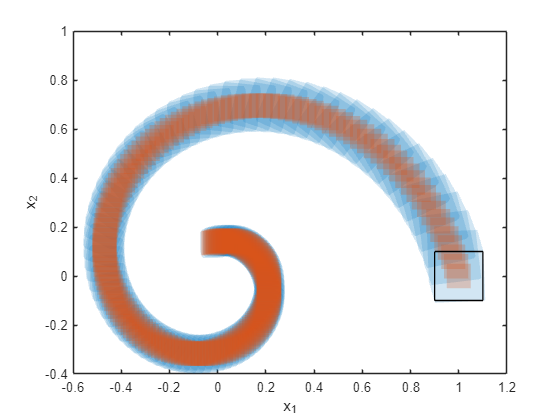

fig = figure();
axe = axes(fig);
hold(axe,"on");
plot(R,[1,2],"FaceAlpha",0.175,"EdgeAlpha",0);
hold(axe,"off");
box(axe,"on");
xlabel("x_1");
ylabel("x_2");

g = @(R)plot(R,[1,2], ...
    "FaceColor",'#D95319', ...
    "FaceAlpha",0.25, ...
    "EdgeAlpha",0);

hold(axe,"on");
cellfun(g,Rk);
cellfun(g,Rint);
plot(R.R0,[1,2],"FaceColor",'w',"FaceAlpha",0);
hold(axe,"off");